# Simulação 11 (Final 5)

## **Erros Orbital**

if isempty(tf)
    tf = 68124;
    t_man = tf/2;
    orb = 12;
    step_modelo = 0.01;
end


%%
figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/(tf/orb);
datax = sqrt(OutCopy(sim_num).Simulation.x_ref.^2 + OutCopy(sim_num).Simulation.y_ref.^2 + OutCopy(sim_num).Simulation.z_ref.^2) - sqrt(OutCopy(sim_num).Simulation.x.^2 + OutCopy(sim_num).Simulation.y.^2 + OutCopy(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2);

%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/60 %min

temp_acom_init = 62.6727

data_man = datax((t_man+1)/step_modelo:end);
infos = stepinfo(data_man,'SettlingTimeThreshold',0.02);
temp_acom_man = infos.TransientTime*step_modelo/60 %min

temp_acom_man = 57.4899


hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/(tf/orb);
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='green');
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/60 %min

temp_acom_init = 69.0271

data_man = datax((t_man+1)/step_modelo:end);
infos = stepinfo(data_man,'SettlingTimeThreshold',0.02);
temp_acom_man = infos.TransientTime*step_modelo/60 %min

temp_acom_man = 63.3145

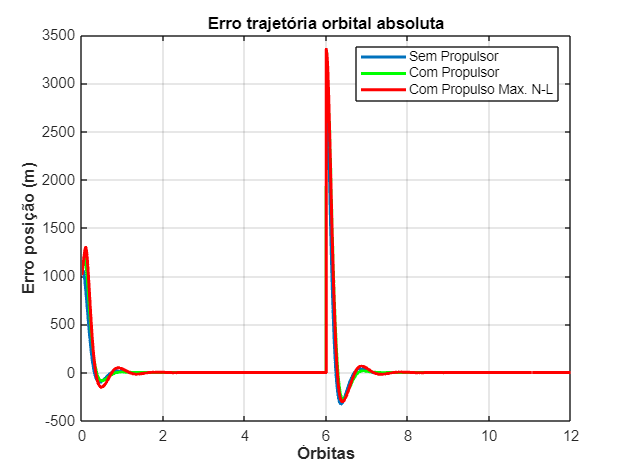


hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/(tf/orb);
%tempo = Out(sim_num).Simulation.tout;
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro trajetória orbital absoluta');
xlabel('Órbitas','LineWidth',2,'Fontweight','bold');
%xlabel('Órbitas');
ylabel('Erro posição (m)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
grid;

%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo/60 %min

temp_acom_init = 99.0247

data_man = datax((t_man+1)/step_modelo:end);
infos = stepinfo(data_man,'SettlingTimeThreshold',0.02);
temp_acom_man = infos.TransientTime*step_modelo/60 %min

temp_acom_man = 83.1767

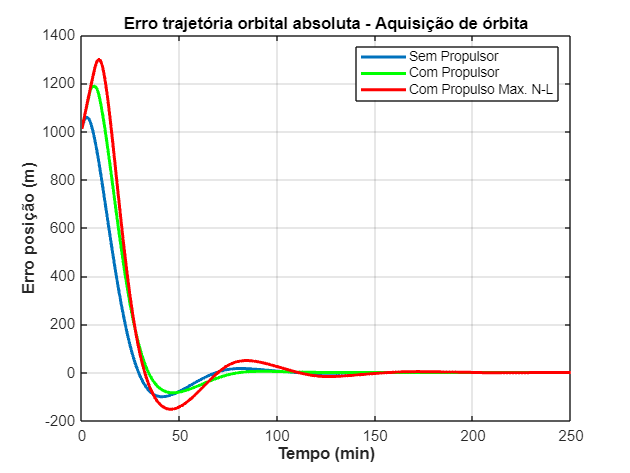


%%
figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/60;
datax = sqrt(OutCopy(sim_num).Simulation.x_ref.^2 + OutCopy(sim_num).Simulation.y_ref.^2 + OutCopy(sim_num).Simulation.z_ref.^2) - sqrt(OutCopy(sim_num).Simulation.x.^2 + OutCopy(sim_num).Simulation.y.^2 + OutCopy(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2);

hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/60;
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='green');

hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/60;
%tempo = Out(sim_num).Simulation.tout;
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro trajetória orbital absoluta - Aquisição de órbita');
xlabel('Tempo (min)','LineWidth',2,'Fontweight','bold');
%xlabel('Órbitas');
ylabel('Erro posição (m)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
xlim([0 250])
grid;

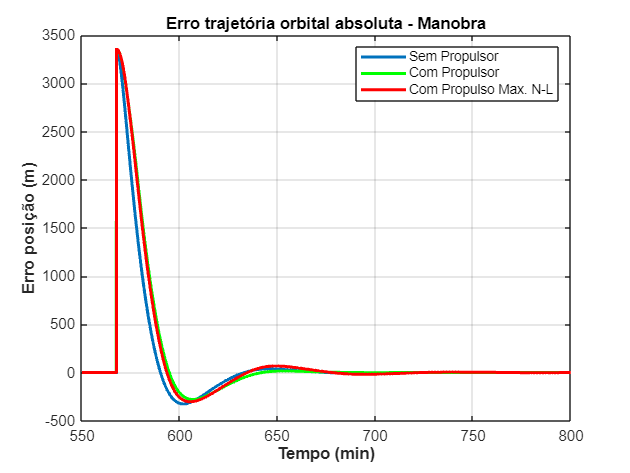

%%
figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/60;
datax = sqrt(OutCopy(sim_num).Simulation.x_ref.^2 + OutCopy(sim_num).Simulation.y_ref.^2 + OutCopy(sim_num).Simulation.z_ref.^2) - sqrt(OutCopy(sim_num).Simulation.x.^2 + OutCopy(sim_num).Simulation.y.^2 + OutCopy(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2);

hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/60;
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='green');

hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/60;
%tempo = Out(sim_num).Simulation.tout;
datax = sqrt(Out(sim_num).Simulation.x_ref.^2 + Out(sim_num).Simulation.y_ref.^2 + Out(sim_num).Simulation.z_ref.^2) - sqrt(Out(sim_num).Simulation.x.^2 + Out(sim_num).Simulation.y.^2 + Out(sim_num).Simulation.z.^2);
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro trajetória orbital absoluta - Manobra');
xlabel('Tempo (min)','LineWidth',2,'Fontweight','bold');
%xlabel('Órbitas');
ylabel('Erro posição (m)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
xlim([550 800])
grid;

## **Atitude**

## **Erro atitude**

%%

figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/1;
datax = rad2deg(OutCopy(sim_num).Simulation.phi_ref) - rad2deg(OutCopy(sim_num).Simulation.phi);
plot(tempo,datax,LineWidth=2);
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 1.8842


hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = rad2deg(Out(sim_num).Simulation.phi_ref) - rad2deg(Out(sim_num).Simulation.phi);
plot(tempo,datax,LineWidth=2,Color='green');
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 186.3194

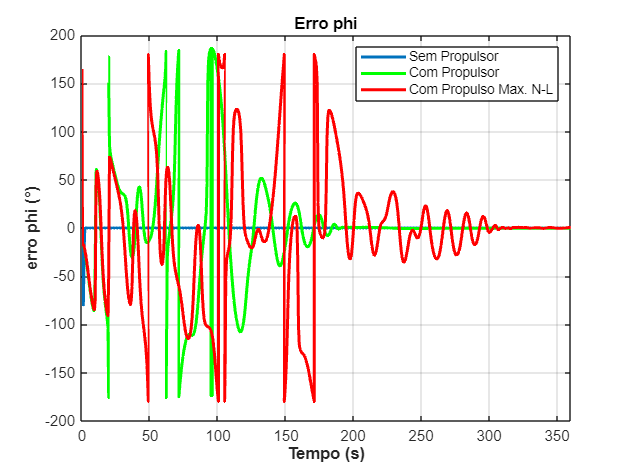


hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = wrapTo180(rad2deg(Out(sim_num).Simulation.phi_ref) - rad2deg(Out(sim_num).Simulation.phi));
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro phi');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
%xlabel('tempo (s)');
ylabel('erro phi (°)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
xlim([0 360])
grid;

%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 301.2184

figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/1;
datax = rad2deg(OutCopy(sim_num).Simulation.theta_ref) - rad2deg(OutCopy(sim_num).Simulation.theta);
plot(tempo,datax,LineWidth=2);
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 3.2281


hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = rad2deg(Out(sim_num).Simulation.theta_ref) - rad2deg(Out(sim_num).Simulation.theta);
plot(tempo,datax,LineWidth=2,Color='green');
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 182.3604

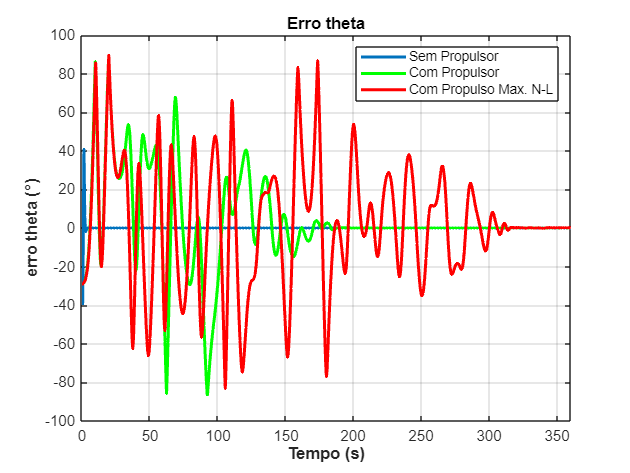


hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = (rad2deg(Out(sim_num).Simulation.theta_ref) - rad2deg(Out(sim_num).Simulation.theta));
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro theta');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
%xlabel('tempo (s)');
ylabel('erro theta (°)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
xlim([0 360])
grid;

%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 311.9404

figure
sim_num = 1;
tempo = OutCopy(sim_num).Simulation.tout/1;
datax = rad2deg(OutCopy(sim_num).Simulation.psi_ref) - rad2deg(OutCopy(sim_num).Simulation.psi);
plot(tempo,datax,LineWidth=2);
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 2.2191


hold on
sim_num = 1;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = rad2deg(Out(sim_num).Simulation.psi_ref) - rad2deg(Out(sim_num).Simulation.psi);
plot(tempo,datax,LineWidth=2,Color='green');
%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 215.6843

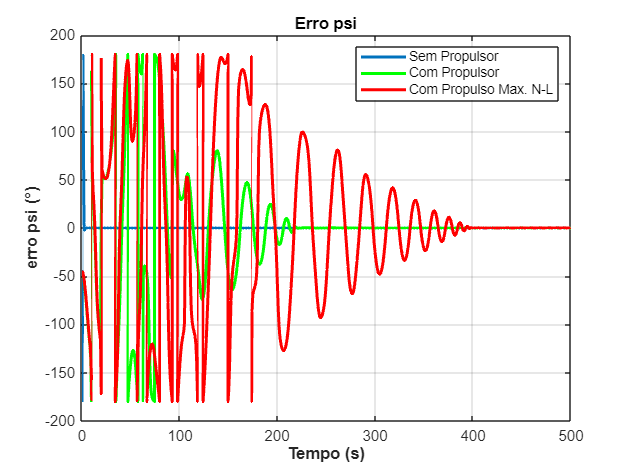


hold on
sim_num = 121;
tempo = Out(sim_num).Simulation.tout/1;
%tempo = Out(sim_num).Simulation.tout;
datax = (rad2deg(Out(sim_num).Simulation.psi_ref) - rad2deg(Out(sim_num).Simulation.psi));
plot(tempo,datax,LineWidth=2,Color='red');
title('Erro psi');
xlabel('Tempo (s)','LineWidth',2,'Fontweight','bold');
%xlabel('tempo (s)');
ylabel('erro psi (°)','LineWidth',2,'Fontweight','bold');
legend('Sem Propulsor','Com Propulsor','Com Propulso Max. N-L');
xlim([0 500])
grid;

%Dados
data_init = datax(1:(t_man-1)/step_modelo);
infos = stepinfo(data_init,'SettlingTimeThreshold',0.02);
temp_acom_init = infos.TransientTime*step_modelo %s

temp_acom_init = 388.1891

## **Tempo de acomodação para posição orbital absoluta**

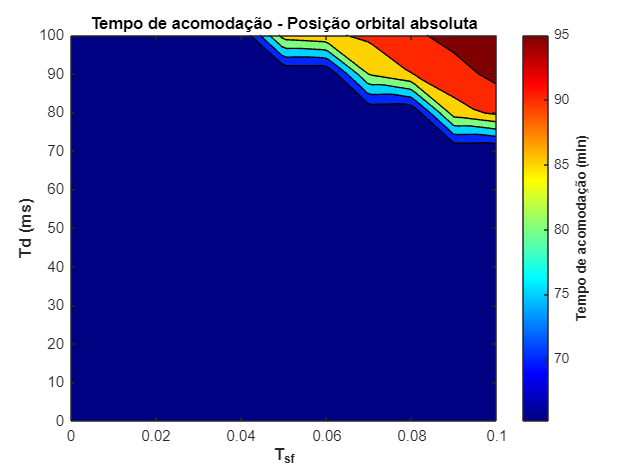

Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_ts = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_ts(count_j,2) = j;
            matriz_plot_ts(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    datax = sqrt(Out(ii).Simulation.x_ref.^2 + Out(ii).Simulation.y_ref.^2 + Out(ii).Simulation.z_ref.^2) - sqrt(Out(ii).Simulation.x.^2 + Out(ii).Simulation.y.^2 + Out(ii).Simulation.z.^2);
    
    datax = datax(1:(t_man-1)/step_modelo);

    infos = stepinfo(datax,'SettlingTimeThreshold',0.02);

    matriz_plot_ts(ii,3) = infos.TransientTime;
end

eixox = matriz_plot_ts(:,1); %eixo x
eixoy = matriz_plot_ts(:,2); %eixo y
eixoz = matriz_plot_ts(:,3)*step_modelo/60; %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure;
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Tempo de acomodação - Posição orbital absoluta')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Tempo de acomodação (min)','LineWidth',2,'Fontweight','bold')

%%

## Erro em regime permanente da posição orbital absoluta

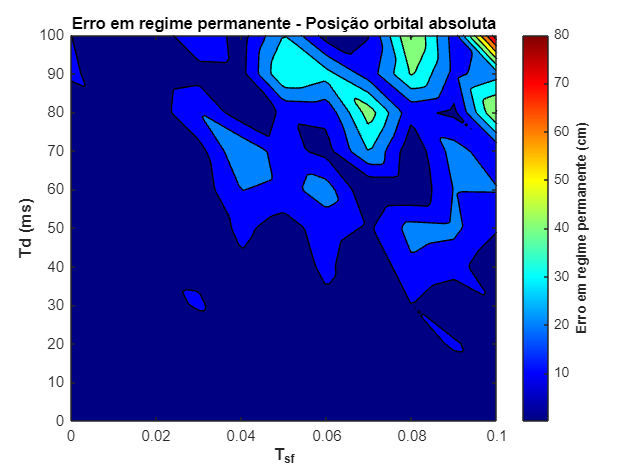


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_err = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_err(count_j,2) = j;
            matriz_plot_err(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    datax = sqrt(Out(ii).Simulation.x_ref.^2 + Out(ii).Simulation.y_ref.^2 + Out(ii).Simulation.z_ref.^2) - sqrt(Out(ii).Simulation.x.^2 + Out(ii).Simulation.y.^2 + Out(ii).Simulation.z.^2);

    %Tempo inicial da órbita 5
    t_init_final = t_man - 1 - tf/12;

    % %Erro em regime permanente é o valor absoluto do último dado antes da
    % manobra orbital

    matriz_plot_err(ii,3) = abs(datax((t_man - 1)/step_modelo));
end

eixox = matriz_plot_err(:,1); %eixo x
eixoy = matriz_plot_err(:,2); %eixo y
eixoz = matriz_plot_err(:,3)*100; %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Erro em regime permanente - Posição orbital absoluta')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Erro em regime permanente (cm)','LineWidth',2,'Fontweight','bold')

## **Tempo de acomodação para atitude **

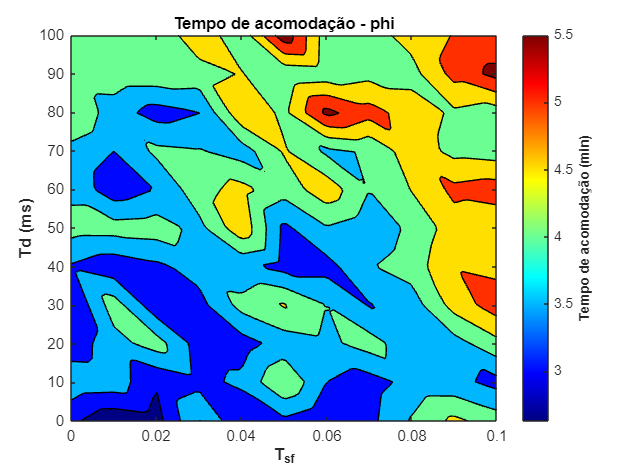

Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_ts_phi = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_ts_phi(count_j,2) = j;
            matriz_plot_ts_phi(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros atitude theta
    data_phi = wrapTo180(rad2deg(Out(ii).Simulation.phi_ref - Out(ii).Simulation.phi));
    data_phi = data_phi(1:(t_man-1)/step_modelo);
    infos = stepinfo(data_phi,'SettlingTimeThreshold',0.02);

    matriz_plot_ts_phi(ii,3) = infos.TransientTime;
end

eixox = matriz_plot_ts_phi(:,1); %eixo x
eixoy = matriz_plot_ts_phi(:,2); %eixo y
eixoz = matriz_plot_ts_phi(:,3)*step_modelo/60; %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure;
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Tempo de acomodação - phi')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Tempo de acomodação (min)','LineWidth',2,'Fontweight','bold')

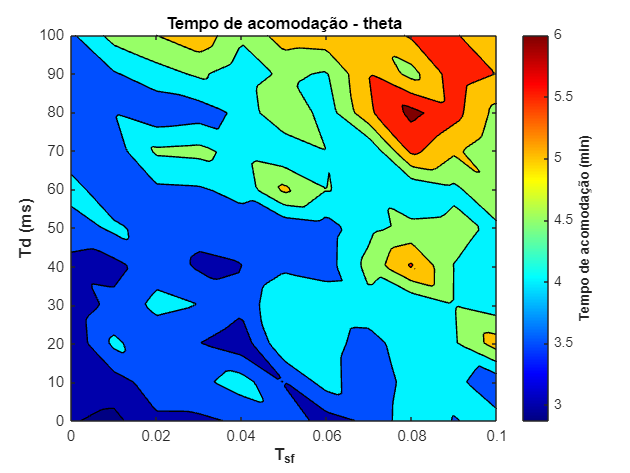


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_ts_theta = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_ts_theta(count_j,2) = j;
            matriz_plot_ts_theta(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros atitude theta
    data_theta = rad2deg(Out(ii).Simulation.theta_ref) - rad2deg(Out(ii).Simulation.theta);
    data_theta = data_theta(1:(t_man-1)/step_modelo);
    infos = stepinfo(data_theta,'SettlingTimeThreshold',0.02);

    matriz_plot_ts_theta(ii,3) = infos.TransientTime;
end

eixox = matriz_plot_ts_theta(:,1); %eixo x
eixoy = matriz_plot_ts_theta(:,2); %eixo y
eixoz = matriz_plot_ts_theta(:,3)*step_modelo/60; %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure;
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Tempo de acomodação - theta')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Tempo de acomodação (min)','LineWidth',2,'Fontweight','bold')

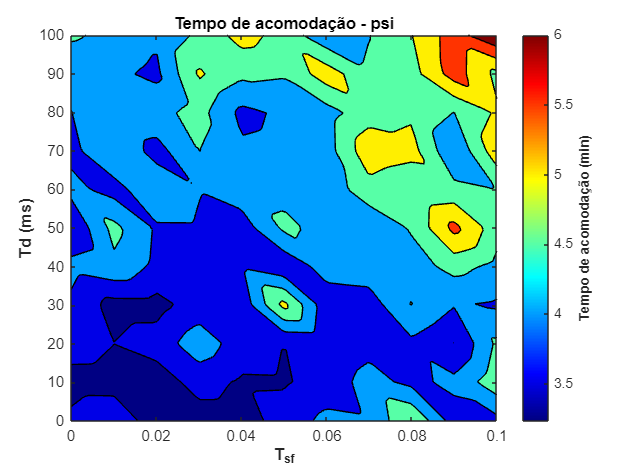


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_ts_psi = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_ts_psi(count_j,2) = j;
            matriz_plot_ts_psi(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros atitude psi
    data_psi = rad2deg(Out(ii).Simulation.psi_ref) - rad2deg(Out(ii).Simulation.psi);
    data_psi = data_psi(1:(t_man-1)/step_modelo);
    infos = stepinfo(data_psi,'SettlingTimeThreshold',0.02);

    matriz_plot_ts_psi(ii,3) = infos.TransientTime;
end

eixox = matriz_plot_ts_psi(:,1); %eixo x
eixoy = matriz_plot_ts_psi(:,2); %eixo y
eixoz = matriz_plot_ts_psi(:,3)*step_modelo/60; %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure;
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Tempo de acomodação - psi')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Tempo de acomodação (min)','LineWidth',2,'Fontweight','bold')

## Erro em regime permanente da atitude

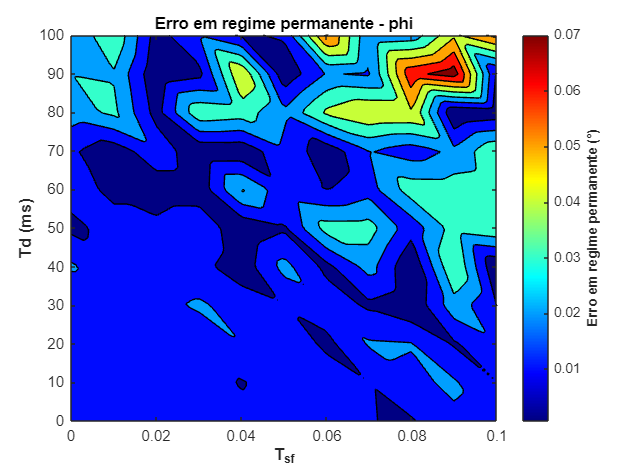

Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_err_phi = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_err_phi(count_j,2) = j;
            matriz_plot_err_phi(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    data_phi = rad2deg(Out(ii).Simulation.phi_ref) - rad2deg(Out(ii).Simulation.phi);

    % %Erro em regime permanente é o valor absoluto do último dado antes da
    % manobra orbital
    matriz_plot_err_phi(ii,3) = abs(data_phi((t_man - 1)/step_modelo));
end

eixox = matriz_plot_err_phi(:,1); %eixo x
eixoy = matriz_plot_err_phi(:,2); %eixo y
eixoz = matriz_plot_err_phi(:,3); %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Erro em regime permanente - phi')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Erro em regime permanente (°)','LineWidth',2,'Fontweight','bold')

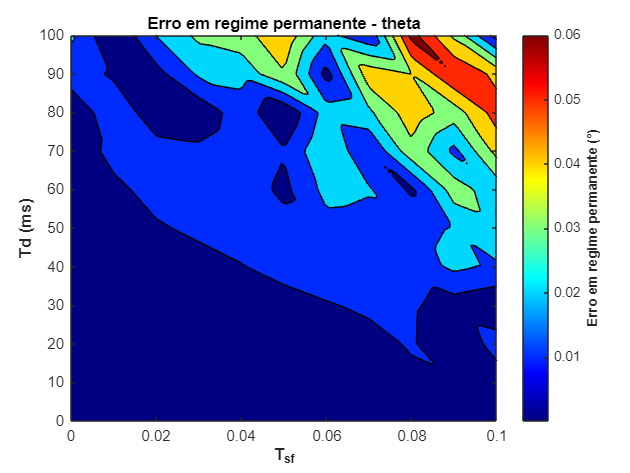


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_err_theta = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_err_theta(count_j,2) = j;
            matriz_plot_err_theta(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    data_theta = rad2deg(Out(ii).Simulation.theta_ref) - rad2deg(Out(ii).Simulation.theta);

    % %Erro em regime permanente é o valor absoluto do último dado antes da
    % manobra orbital
    matriz_plot_err_theta(ii,3) = abs(data_theta((t_man - 1)/step_modelo));
end

eixox = matriz_plot_err_theta(:,1); %eixo x
eixoy = matriz_plot_err_theta(:,2); %eixo y
eixoz = matriz_plot_err_theta(:,3); %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Erro em regime permanente - theta')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Erro em regime permanente (°)','LineWidth',2,'Fontweight','bold')

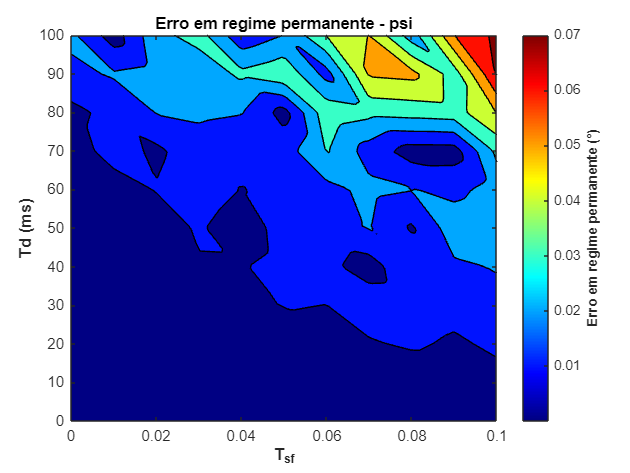


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_err_psi = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_err_psi(count_j,2) = j;
            matriz_plot_err_psi(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    data_psi = rad2deg(Out(ii).Simulation.psi_ref) - rad2deg(Out(ii).Simulation.psi);

    % %Erro em regime permanente é o valor absoluto do último dado antes da
    % manobra orbital
    matriz_plot_err_psi(ii,3) = abs(data_psi((t_man - 1)/step_modelo));
end

eixox = matriz_plot_err_psi(:,1); %eixo x
eixoy = matriz_plot_err_psi(:,2); %eixo y
eixoz = matriz_plot_err_psi(:,3); %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Erro em regime permanente - psi')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Erro em regime permanente (°)','LineWidth',2,'Fontweight','bold')

## Gasto de combustível total

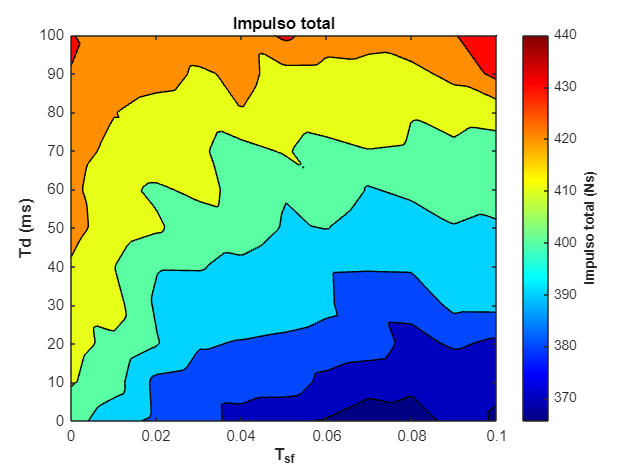


Tpulse_size = 0:0.01:0.1; %Tpulse
Td_size = 0:10:100; %Td
t_manobra_size = length(Tpulse_size)*length(Td_size);

matriz_plot_comb = zeros(t_manobra_size,3);

count_j = 1;

for i = 0:0.01:0.1 %Tpulse
        for j = 0:10:100 %Td
            matriz_plot_comb(count_j,2) = j;
            matriz_plot_comb(count_j,1) = i;
            count_j = count_j + 1;
        end
end

for ii = 1:1:t_manobra_size
    %Erros orbitais absolutos
    datax = Out(ii).Simulation.impulso(end);

    matriz_plot_comb(ii,3) = datax;
end

eixox = matriz_plot_comb(:,1); %eixo x
eixoy = matriz_plot_comb(:,2); %eixo y
eixoz = matriz_plot_comb(:,3); %cor

x_lim = linspace(0,0.1);
y_lim = linspace(0,100);

[xstart,ystart] = meshgrid(x_lim,y_lim);
zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);

figure
contourf(xstart,ystart,zstart)
xlabel('T_{sf}','LineWidth',2,'Fontweight','bold')
ylabel('Td (ms)','LineWidth',2,'Fontweight','bold')
title('Impulso total')
colormap(jet)
hcb=colorbar;
%hcb.Title.String = "t_s (s)";
ylabel(hcb,'Impulso total (Ns)','LineWidth',2,'Fontweight','bold')

## Quantidade de pulsos totais

% Tpulse_size = 0:0.01:0.1; %Tpulse
% Td_size = 0:10:100; %Td
% t_manobra_size = length(Tpulse_size)*length(Td_size);
% 
% matriz_plot_pul = zeros(t_manobra_size,3);
% 
% count_j = 1;
% 
% for i = 0:0.01:0.1 %Tpulse
%         for j = 0:10:100 %Td
%             matriz_plot_pul(count_j,2) = j;
%             matriz_plot_pul(count_j,1) = i;
%             count_j = count_j + 1;
%         end
% end
% 
% for ii = 1:1:t_manobra_size
%     %Somatório dos pulsos individuais
%     indSom = sum(Out(ii).Simulation.pulsos(:,:));
% 
%     %Somatório dos pulsos totais
%     totSom = sum(indSom);
% 
%     matriz_plot_pul(ii,3) = totSom;
% end
% 
% eixox = matriz_plot_pul(:,1); %eixo x
% eixoy = matriz_plot_pul(:,2); %eixo y
% eixoz = matriz_plot_pul(:,3); %cor
% 
% x_lim = linspace(0,0.1);
% y_lim = linspace(0,100);
% 
% [xstart,ystart] = meshgrid(x_lim,y_lim);
% zstart = griddata(eixox,eixoy,eixoz,xstart,ystart);
% 
% figure
% contourf(xstart,ystart,zstart)
% xlabel('Tpulse (s)')
% ylabel('Td (s)')
% %title('Settling time - X')
% colormap(jet)
% hcb=colorbar;
% %hcb.Title.String = "t_s (s)";
% ylabel(hcb,'Quantidade de pulsos')

% for ii = 1:1:t_manobra_size
%     %Erros orbitais absolutos
%     datax = sqrt(Out(ii).Simulation.x_ref.^2 + Out(ii).Simulation.y_ref.^2 + Out(ii).Simulation.z_ref.^2) - sqrt(Out(ii).Simulation.x.^2 + Out(ii).Simulation.y.^2 + Out(ii).Simulation.z.^2);
% 
%     %Tempo inicial da órbita 5
%     t_init_final = t_man - 1 - tf/12;
% 
%     %Erro em regime permanente, que é a média dos erros entre a órbita 5 e 6
%     erro_rp = abs(mean(datax(t_init_final/step_modelo:(t_man-1)/step_modelo)));
% 
%     %Acrescimo de 5% no erro de regime permanente
%     erro_rp_final = erro_rp*1.05;
% 
%     %Tempo de manobra é o tempo em que a posição absoluta está fora do erro em
%     %regime permanente pela primeira vez, iniciando de trás para frente na
%     %órbita
% 
%     for iii=1:10000:((t_man-1)/step_modelo)
%         if abs(mean((datax(iii:iii+10000)))) < erro_rp_final
%             t_manobra = iii;
%             break
%         end
%     end
% 
%     t_manobra = t_manobra*step_modelo;
%     matriz_plot(ii,3) = t_manobra;
% end



